Data l'immagine lenarumorosa.y (di dimensioni 512 x 512, int16) corrotta da rumore sinusoidale, si vuole rimuovere il rumore mediante un opportuno fi�ltraggio.

    1. Nello script ex2.m calcolate e visualizzate opportunamente la trasformata di Fourier dell'immagine;

    2. scrivete una funzione function y = rimuovi(x) in cui progettate un �ltro nel dominio di Fourier capace di eliminare il rumore sinusoidale e  visualizzatene la risposta in frequenza; mostrate inoltre l'immagine �ltrata e la sua trasformata di Fourier e valutate l'MSE con l'originale memorizzata nel �le lena.y (di dimensioni 512 x 512, uint8).

fid = fopen('lenarumorosa.y','rb');
x = fread(fid,[512 512],'int16');
x = x';
fclose(fid);

% Definizione griglia
[M,N] = size(x);
n = -1/2:1/N:1/2-1/N;
m = -1/2:1/M:1/2-1/M;
[l,k] = meshgrid(n,m);

% DFT
X = fftshift(fft2(x));

% Filtro
sigma = 0.08;
C = [0.2 -0.2; -0.2 0.2];   % centri
H = ones(N,M);
for i = 1:2,
    D = sqrt((l-C(i,1)).^2+(k-C(i,2)).^2);
    H = H - exp(-D.^2/(2*sigma^2));
end

% Filtraggio
Y = X.*H;
y = real(ifft2(ifftshift(Y)));

% MSE
fid = fopen('lena.y','rb');
xo = fread(fid,[512 512],'uint8');
xo = xo';
fclose(fid);
MSE = mean2((y-xo).^2)

MSE = 19.2376

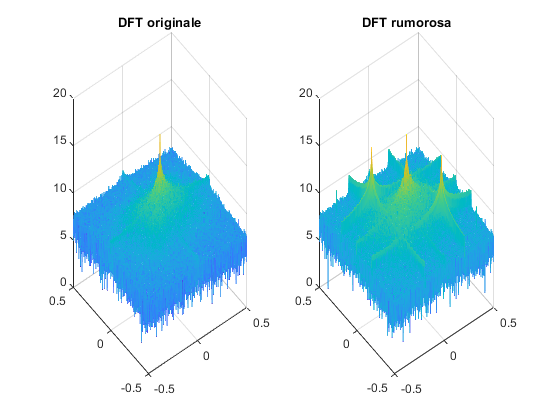


% DFT originale/rumorosa
Xo = fftshift(fft2(xo));
figure; 
subplot(121); mesh(l,k,log(1+abs(Xo))); title('DFT originale');
subplot(122); mesh(l,k,log(1+abs(X))); title('DFT rumorosa');

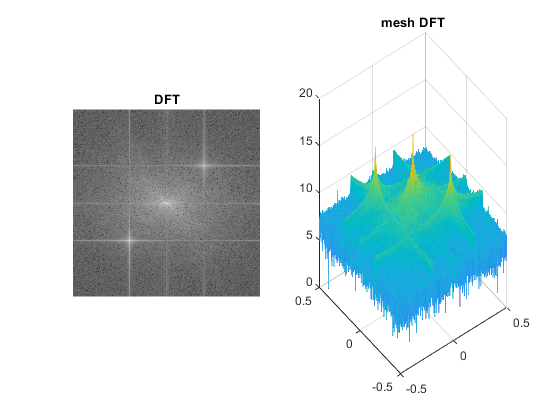


% Visualizzazione
figure; 
subplot(121); imshow(log(1+abs(X)),[]); title('DFT');
subplot(122); mesh(l,k,log(1+abs(X))); title('mesh DFT');

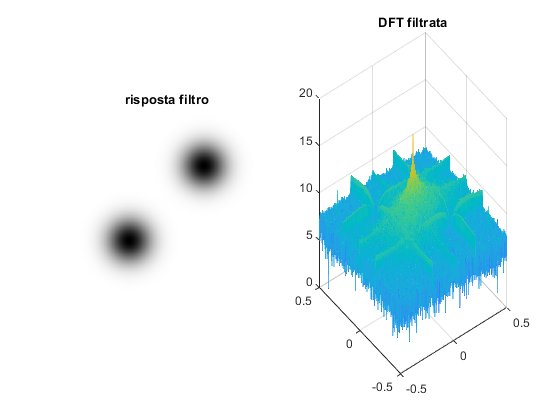

figure; 
subplot(121); imshow(H,[]); title('risposta filtro');
subplot(122); mesh(l,k,log(1+abs(Y))); title('DFT filtrata');

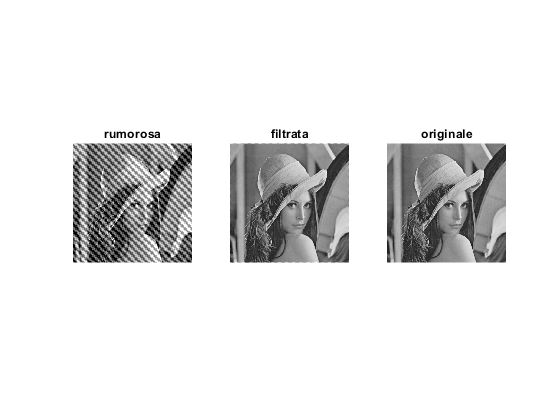

figure;
subplot(131); imshow(x,[0 255]); title('rumorosa');
subplot(132); imshow(y,[0 255]); title('filtrata');
subplot(133); imshow(xo,[0 255]); title('originale');